clear all
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [9, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Node", "Nominal_stress", "X_heigth", "Ymm", "Var5"];
opts.SelectedVariableNames = ["Node", "Nominal_stress", "X_heigth", "Ymm"];
opts.VariableTypes = ["double", "double", "double", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Var5", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var5", "EmptyFieldRule", "auto");

% Import the data
tbl = readtable("Stress_data.csv", opts);


data = table2array(tbl);
Y_data = data(:,4);

% data3 = data((data(:,1)<N_D) && (data(:,3)==0))
data_sort = [];
Y_line = 45.77

Y_line =         45.77


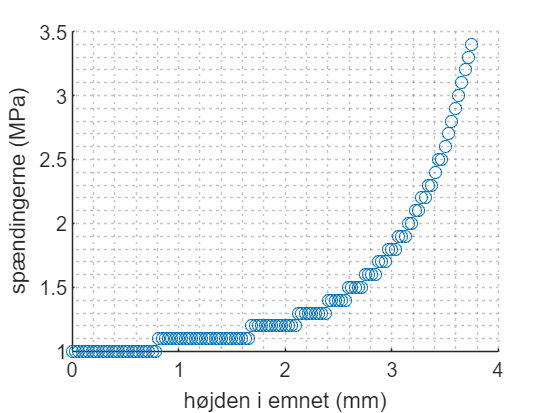


for i = 1:length(data(:,1))
    if Y_data(i) == Y_line
        data_sort(end+1,2:3) = data(i,2:3);
    end
end


sigma = data_sort(:,2);
x = data_sort(:,3);

scatter(x, sigma)
% plot(x, sigma)
xlabel("højden i emnet (mm)")
ylabel("spændingerne (MPa)")
grid('minor')

F = 100; %N
A = pi*max(x)^2;
sigma_k = sigma %Fe spændingerne

sigma_k =           3.4
          3.2
            3
          2.8
          2.6
          2.5
          2.3
          2.2
          2.1
            2


sigma_n = F/A

sigma_n =        2.2635



K_t = sigma_k/sigma_n

K_t =        1.5021
       1.4137
       1.3254
        1.237
       1.1486
       1.1045
       1.0161
      0.97193
      0.92775
      0.88357


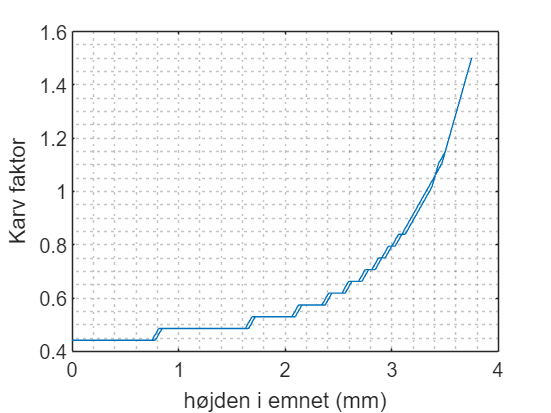

plot(x,K_t)
xlabel("højden i emnet (mm)")
ylabel("Karv faktor")
grid('minor')


$$\chi^* = \left| \frac{\Delta\sigma}{\sigma_{k,max} \Delta x} \right|$$



X_grad = ((sigma(1)/max(sigma_k)- sigma(2)/max(sigma_k)))/(x(1) - x(2))%abs(1/max(sigma_k))

X_grad =       0.94118
